# **RS-WISP-08-04: GEO AR&D Trajectory Generation **

**WorkerInSpace**

**Hongseok Kim**

**2025/07/07**

## I. Phase 1: GTO to near-GEO transfer

mu = 398600.4415;
r_p = 6378 + 200;
r_a = 6378 + 36000;
inc = 28;
number_of_transfer = 5;

[inc_vec, ecc_vec, delta_v_y, delta_v_z] = GTO_to_GEO_trajectory(r_a, r_p, inc, number_of_transfer)

inc_vec =   28.000000000000007
  18.977220978264462
  12.213194400646653
   7.086297418416515
   3.124983898539271
                   0


ecc_vec =    0.731268894517526
   0.641543713686649
   0.523554233819458
   0.377300454915953
   0.202782376976134
                   0


delta_v_y =    0.332626848349252


delta_v_z =   -0.149278380680994


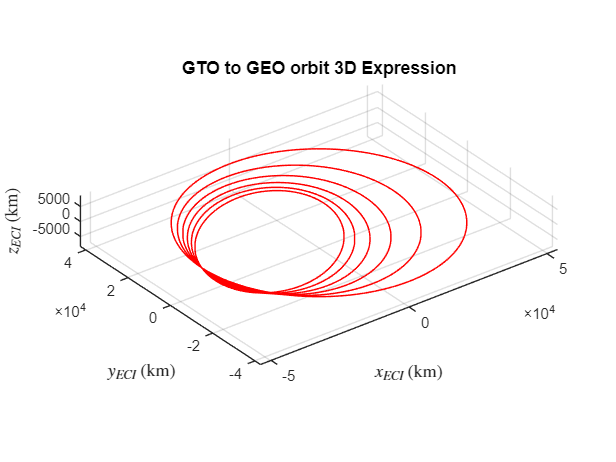



%% Define Initial Orbit Parameter

figure;
hold on


for i = 1:number_of_transfer+1 

ecc = ecc_vec(i);
SMA = r_a / (1+ecc); 
inc = inc_vec(i);
RAAN = 0;
AOP = 0;
theta = 0;
orbit_period = 2*pi* sqrt(SMA^3/mu);
time_vector = [0:1:orbit_period, orbit_period];
[r0,v0]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);
[t,y] = orbit_propagation(r0,v0,time_vector);
r = y(:,1:3);
v = y(:,4:6);
vel_aps(2) = norm(v(1,:));
plot3(r(:,1),r(:,2),r(:,3),'LineWidth',1,'Color','r')

end
axis('equal')
view(3)
hold off
title('GTO to GEO orbit 3D Expression','FontSize',12,'FontWeight','bold')
xlabel('$x_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',12) 
ylabel('$y_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',12)
zlabel('$z_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',12)
grid on


fprintf('total %4.0f impulse burns',number_of_transfer)

total    5 impulse burns

fprintf('Total Delta v is: in-track %4.4f km/s, cross-track %4.4f km/s',  delta_v_y*number_of_transfer, delta_v_z*number_of_transfer)

Total Delta v is: in-track 1.6631 km/s, cross-track -0.7464 km/s

fprintf('Delta v per burn is: in-track %4.4f km/s, cross-track %4.4f km/s',  delta_v_y, delta_v_z)

Delta v per burn is: in-track 0.3326 km/s, cross-track -0.1493 km/s

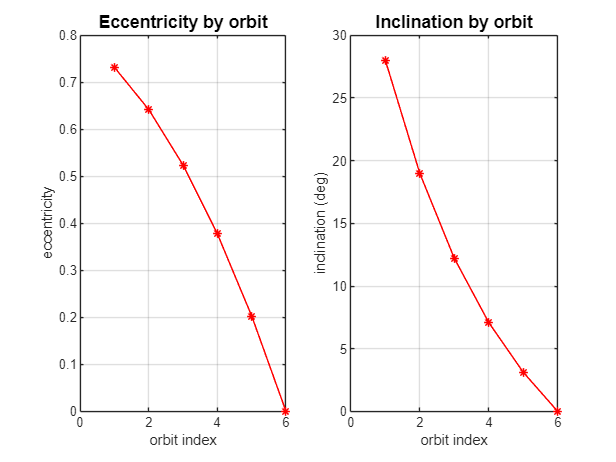


figure;
subplot(1,2,1)
plot(1:number_of_transfer+1, ecc_vec,'r','LineWidth',1,'Marker','*')
title('Eccentricity by orbit','FontSize',12,'FontWeight','bold')
grid on
xlabel('orbit index')
ylabel('eccentricity')


subplot(1,2,2)
plot(1:number_of_transfer+1, inc_vec,'r','LineWidth',1,'Marker','*')
title('Inclination by orbit','FontSize',12,'FontWeight','bold')
grid on
xlabel('orbit index')
ylabel('inclination (deg)')




function [inc_vec, ecc_vec, delta_v_y, delta_v_z] = GTO_to_GEO_trajectory(r_a, r_p, i, n)

% Step 1: get initial velocity vector
mu = 398600.4415;
r = r_a;
a = (r_a + r_p)/2;
v = sqrt(mu * (2/r - 1/a));
v_y0 = v * cos(i /180*pi);
v_z0 = v * sin(i /180*pi);

% Step 2: get final velocity vector
v_yn = sqrt(mu/r_a);
v_zn = 0;
delta_v_y = 1/n * (v_yn - v_y0);
delta_v_z = 1/n * (v_zn - v_z0);

% Step 3: get matrix of velocity vector for each revolution
velocity_info_mat = zeros(n+1,2);
for i = 0:n
velocity_info_mat(i+1,1) = v_y0 + i * delta_v_y;
velocity_info_mat(i+1,2) = v_z0 + i * delta_v_z;
end

% Step 4: get matrix of eccentricity and inclination for each revolution
inc_vec = zeros(n+1,1);
ecc_vec = zeros(n+1,1);

for i = 0:n

v_y = velocity_info_mat(i+1,1);
v_z = velocity_info_mat(i+1,2);

ecc = 1-r_a * (v_y^2 + v_z^2)/mu;

sin_i = v_z / sqrt(v_y^2+v_z^2);
cos_i = v_y / sqrt(v_y^2+v_z^2);

    if sin_i >= 0 
        inc = acos(cos_i)/pi*180;
    else
        inc = (2*pi - acos(cos_i))/pi*180;
    end

ecc_vec(i+1) = ecc;
inc_vec(i+1) = inc;

end

end

## II. Phase 2: Co-Elliptic Rendezvous with Hohmann Raises

radius_of_chaser = 6378 + 36000 - 30;
radius_of_target = 6378 + 36000;
TA_of_chaser = 29;
TA_of_target = 30;
number_of_transfer = 5;


SMA = radius_of_chaser; 
theta = TA_of_chaser;
inc = 0;
RAAN = 0;
AOP = 0;
ecc = 0;
[r_chaser,v_chaser]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);


SMA = radius_of_target; 
theta = TA_of_target;
inc = 0;
RAAN = 0;
AOP = 0;
ecc = 0;
[r_target,v_target]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);

[delta_v_1_vec, delta_v_2_vec, t_H_vec, t_E_vec] = hohmann_and_co_elliptic(r_chaser, r_target, number_of_transfer)

delta_v_1_vec = 1.0e-03 *

   0.108660658935997
   0.108637571304204
   0.108614491846416
   0.108591420559071
   0.108568357439289


delta_v_2_vec = 1.0e-03 *

   0.108656810429561
   0.108633724160126
   0.108610646064579
   0.108587576139019
   0.108564514379203


t_H_vec = 1.0e+04 *

   4.336870848903747
   4.337792508842082
   4.338714234060719
   4.339636024555034
   4.340557880320406


t_E_vec = 1.0e+05 *

   0.063545612159316
   0.187864018294612
   0.395122802062331
   0.809732539702535
   2.053746112413327




fprintf('Co-Elliptic Duration for each manuver is : \n')

Co-Elliptic Duration for each manuver is : 


fprintf('%4.1f seconds \n',t_E_vec)

6354.6 seconds 
18786.4 seconds 
39512.3 seconds 
80973.3 seconds 
205374.6 seconds 


fprintf('Hohmann-Transfer Duration for each manuver is : \n')

Hohmann-Transfer Duration for each manuver is : 


fprintf('%4.1f seconds \n',t_H_vec)

43368.7 seconds 
43377.9 seconds 
43387.1 seconds 
43396.4 seconds 
43405.6 seconds 



fprintf('Hohmann Transfer Starting delta_v for each maneuver is: \n')

Hohmann Transfer Starting delta_v for each maneuver is: 


fprintf('%4.8f m/s \n',delta_v_1_vec*1000)

0.10866066 m/s 
0.10863757 m/s 
0.10861449 m/s 
0.10859142 m/s 
0.10856836 m/s 



fprintf('Hohmann Transfer ending delta_v for each maneuver is: \n')

Hohmann Transfer ending delta_v for each maneuver is: 


fprintf('%4.8f m/s \n',delta_v_2_vec*1000)

0.10865681 m/s 
0.10863372 m/s 
0.10861065 m/s 
0.10858758 m/s 
0.10856451 m/s 


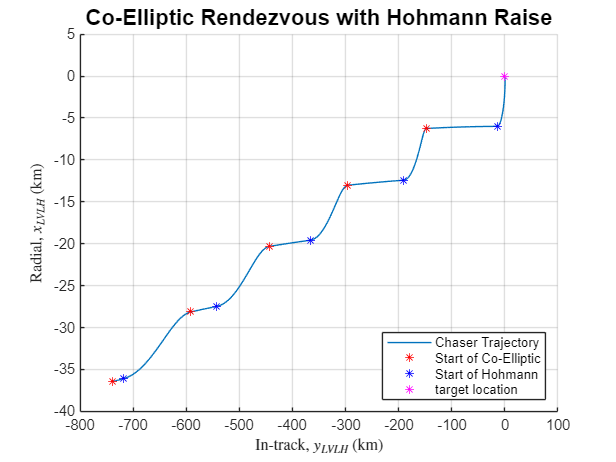


r_chaser_eci_info = r_chaser';
v_chaser_eci_info = v_chaser';
r_target_eci_info = r_target';
v_target_eci_info = v_target';

co_elliptic_start_r_chaser = [];
co_elliptic_start_r_target = [];
co_elliptic_start_v_chaser = [];
co_elliptic_start_v_target = [];

hohmann_start_r_chaser = [];
hohmann_start_r_target = [];
hohmann_start_v_chaser = [];
hohmann_start_v_target = [];

for i = 1:number_of_transfer

t_E = linspace(0,t_E_vec(i));
t_H = linspace(0,t_H_vec(i));
delta_v_1 = delta_v_1_vec(i);
delta_v_2 = delta_v_2_vec(i);

% Co-elliptic transfer

[t,y_c] = orbit_propagation(r_chaser_eci_info(end,:)', v_chaser_eci_info(end,:)', t_E);
[t,y_t] = orbit_propagation(r_target_eci_info(end,:)', v_target_eci_info(end,:)', t_E);

co_elliptic_start_r_chaser = [co_elliptic_start_r_chaser;r_chaser_eci_info(end,:)];
co_elliptic_start_r_target = [co_elliptic_start_r_target;r_target_eci_info(end,:)];
co_elliptic_start_v_chaser = [co_elliptic_start_v_chaser;v_chaser_eci_info(end,:)];
co_elliptic_start_v_target = [co_elliptic_start_v_target;v_target_eci_info(end,:)];



r_chaser_eci_info = [r_chaser_eci_info;y_c(:,1:3)];
v_chaser_eci_info = [v_chaser_eci_info;y_c(:,4:6)];

r_target_eci_info = [r_target_eci_info;y_t(:,1:3)];
v_target_eci_info = [v_target_eci_info;y_t(:,4:6)];


% Hohmann-transfer

r_c_eci = r_chaser_eci_info(end,:);
v_c_eci = v_chaser_eci_info(end,:);
v_c_eci_updated = v_c_eci / norm(v_c_eci) * (norm(v_c_eci)+delta_v_1);

r_t_eci = r_target_eci_info(end,:);
v_t_eci = v_target_eci_info(end,:);

hohmann_start_r_chaser = [hohmann_start_r_chaser; r_c_eci];
hohmann_start_r_target = [hohmann_start_r_target; r_t_eci];
hohmann_start_v_chaser = [hohmann_start_v_chaser; v_c_eci_updated];
hohmann_start_v_target = [hohmann_start_v_target; v_t_eci];

[t,y_c] = orbit_propagation(r_c_eci', v_c_eci_updated', t_H);
[t,y_t] = orbit_propagation(r_t_eci', v_t_eci', t_H);

r_chaser_eci_info = [r_chaser_eci_info;y_c(:,1:3)];
v_chaser_eci_info = [v_chaser_eci_info;y_c(:,4:6)];

v_chaser_eci_info(end,:) = v_chaser_eci_info(end,:) /  norm(v_chaser_eci_info(end,:)) * (norm(v_chaser_eci_info(end,:)) + delta_v_2);

r_target_eci_info = [r_target_eci_info;y_t(:,1:3)];
v_target_eci_info = [v_target_eci_info;y_t(:,4:6)];

end


r_lvlh_info = zeros(length(r_chaser_eci_info(:,1)),3);
v_lvlh_info = zeros(length(r_chaser_eci_info(:,1)),3);

for time_index = 1:length(r_chaser_eci_info(:,1))

    r_t_eci_current = r_target_eci_info(time_index,:)';
    v_t_eci_current = v_target_eci_info(time_index,:)';
    r_c_eci_current = r_chaser_eci_info(time_index,:)';
    v_c_eci_current = v_chaser_eci_info(time_index,:)';
    n = sqrt(mu/(norm(r_t_eci_current)^3));

    [r_lvlh_current, v_lvlh_current] = eci2lvlh(r_t_eci_current, v_t_eci_current, r_c_eci_current, v_c_eci_current, n);
    r_lvlh_info(time_index,:) = r_lvlh_current';
    v_lvlh_info(time_index,:) = v_lvlh_current';    
end

co_elliptic_start_r_LVLH_info = zeros(number_of_transfer,3);
co_elliptic_start_v_LVLH_info = zeros(number_of_transfer,3);
hohmann_start_r_LVLH_info = zeros(number_of_transfer,3);
hohmann_start_v_LVLH_info = zeros(number_of_transfer,3);

for transfer_index = 1:number_of_transfer

  hohmann_start_r_target_current = hohmann_start_r_target(transfer_index,:)';
  hohmann_start_r_chaser_current = hohmann_start_r_chaser(transfer_index,:)';
  hohmann_start_v_target_current = hohmann_start_v_target(transfer_index,:)';
  hohmann_start_v_chaser_current = hohmann_start_v_chaser(transfer_index,:)';
  n_hohmann = sqrt(mu/(norm(hohmann_start_r_target_current)^3));

  co_elliptic_start_r_target_current = co_elliptic_start_r_target(transfer_index,:)';
  co_elliptic_start_r_chaser_current = co_elliptic_start_r_chaser(transfer_index,:)';
  co_elliptic_start_v_target_current = co_elliptic_start_v_target(transfer_index,:)';
  co_elliptic_start_v_chaser_current = co_elliptic_start_v_chaser(transfer_index,:)';
  n_co_elliptic = sqrt(mu/(norm(co_elliptic_start_r_target_current)^3));

  [co_elliptic_start_r_LVLH , co_elliptic_start_v_LVLH] = eci2lvlh(co_elliptic_start_r_target_current,co_elliptic_start_v_target_current, ...
                                                                   co_elliptic_start_r_chaser_current,co_elliptic_start_v_chaser_current, ...
                                                                   n_co_elliptic );
  [hohmann_start_r_LVLH , hohmann_start_v_LVLH] = eci2lvlh(hohmann_start_r_target_current,hohmann_start_v_target_current, ...
                                                           hohmann_start_r_chaser_current, hohmann_start_v_chaser_current, ...
                                                           n_hohmann);

  co_elliptic_start_r_LVLH_info(transfer_index,:) = co_elliptic_start_r_LVLH;
  co_elliptic_start_v_LVLH_info(transfer_index,:)  = co_elliptic_start_v_LVLH;
  hohmann_start_r_LVLH_info(transfer_index,:)  = hohmann_start_r_LVLH;
  hohmann_start_v_LVLH_info(transfer_index,:)  = hohmann_start_v_LVLH;

end



figure;
hold on
plot(r_lvlh_info(:,2),r_lvlh_info(:,1))
scatter(co_elliptic_start_r_LVLH_info(:,2),co_elliptic_start_r_LVLH_info(:,1),'*','r')
scatter(hohmann_start_r_LVLH_info(:,2),hohmann_start_r_LVLH_info(:,1),'*','b')
scatter(0,0,'*','m')
grid on
title('Co-Elliptic Rendezvous with Hohmann Raise','FontSize',15,'FontWeight','bold')
xlabel('In-track,  $y_{LVLH}$ (km)', 'Interpreter', 'latex')
ylabel('Radial,  $x_{LVLH}$ (km)', 'Interpreter', 'latex')
legend('Chaser Trajectory', 'Start of Co-Elliptic','Start of Hohmann','target location','Location','southeast')





function [delta_v_1_vec, delta_v_2_vec, t_H_vec, t_E_vec] = hohmann_and_co_elliptic(r_chaser, r_target, n)
mu = 398600.4415;
% Step 1: get delta_theta

     x_c_eci = r_chaser(1);
     y_c_eci = r_chaser(2);
     x_t_eci = r_target(1);
     y_t_eci = r_target(2);
    
    if y_c_eci >=0
        theta_c = acos(x_c_eci / sqrt(x_c_eci^2+y_c_eci^2));
    else
        theta_c = 2*pi - acos(x_c_eci / sqrt(x_c_eci^2+y_c_eci^2));
    end
    
    if y_t_eci >=0
        theta_t = acos(x_t_eci / sqrt(x_t_eci^2+y_t_eci^2));
    else
        theta_t = 2*pi - acos(x_t_eci / sqrt(x_t_eci^2+y_t_eci^2));
    end
    
    delta_theta = theta_t - theta_c;
    delta_theta_i = - delta_theta/n;
% Step 2: get chaser radius information

    r_0 = norm(r_chaser);
    r_n = norm(r_target);
    delta_r = (r_n - r_0)/n;
    
    radius_vec = zeros(n+1,1);
    
    for i = 0:n
        radius_vec(i+1) = r_0 + i *delta_r;
    end

% Step 3: Hohmann transfer design

delta_v_1_vec = zeros(n,1);
delta_v_2_vec = zeros(n,1);
t_H_vec = zeros(n,1);
t_E_vec = zeros(n,1);

for i = 1:n

    r_i_minus_1 = radius_vec(i);
    r_i = radius_vec(i+1);
    % 
    % delta_v_i1 = sqrt(2*mu*r_i/r_i_minus_1/(r_i+r_i_minus_1)-sqrt(mu/r_i_minus_1));
    % delta_v_i2 = sqrt(mu/r_i) - sqrt(2*mu*r_i_minus_1/r_i/(r_i+r_i_minus_1));

   delta_v_i1 = sqrt(mu/r_i_minus_1) * (sqrt(2*r_i/(r_i_minus_1 + r_i))-1);
   delta_v_i2 = sqrt(mu/r_i) * (1 - sqrt(2*r_i_minus_1/(r_i_minus_1 + r_i)));



    t_Hi =  pi * sqrt((r_i_minus_1 + r_i)^3/(8*mu));

% Step 4: Co-elliptic design
    delta_theta_Hi = sqrt(mu/r_n^3)*t_Hi-pi;
    t_Ei = (delta_theta_i - delta_theta_Hi)/(sqrt(mu/r_n^3)-sqrt(mu/r_i_minus_1^3));

    delta_v_1_vec(i) = delta_v_i1;
    delta_v_2_vec(i) = delta_v_i2;
    t_H_vec(i) = t_Hi;
    t_E_vec(i) = t_Ei;

 end

end

## III. Phase 3: Walking Safety Ellipse Approach

### III.1 Generate WSE for single $r_{\textrm{LVLH}} ,v_{\textrm{LVLH}} ,n_{\textrm{target}}$

r_target_eci = r_target_eci_info(end,:);

r_lvlh = hohmann_start_r_LVLH_info(end,:)';
v_lvlh = hohmann_start_v_LVLH_info(end,:)';
n_target_vehicle = sqrt(mu/norm(r_target_eci)^3);
x_0 = r_lvlh(1); y_0 = r_lvlh(2); z_0 = r_lvlh(3);
x_dot_0 = v_lvlh(1); y_dot_0 = v_lvlh(2); z_dot_0 = v_lvlh(3);

n = n_target_vehicle;

format short
[x_max, y_max, z_max, x_c, y_c, y_dot_c, alpha, beta] = get_safety_ellipse_params(x_0, y_0, z_0, x_dot_0, y_dot_0, z_dot_0, n)

x_max = 2.9939

y_max = 5.9879

z_max = 0

x_c = -3.0084

y_c = -14.1419

y_dot_c = 3.2658e-04

alpha = 3.1428

beta = 0

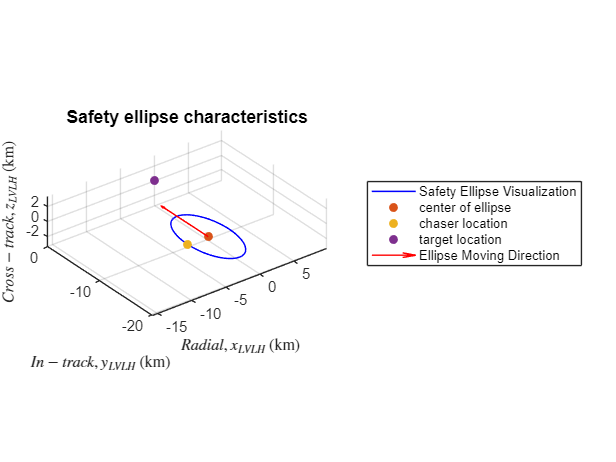


  % Option: Plot the safety ellipse
   figure;
   hold on
   grid on
   nt = linspace(0,2*pi);
   x_t = x_max * cos(nt + alpha) + x_c;
   y_t = -2 * x_max * sin(nt+alpha) + y_c;
   z_t = z_max * cos(nt + beta);

   plot3(x_t, y_t, z_t,'blue','LineWidth',1)
   scatter3(x_c,y_c,0,'filled') % Center of Ellipse
   scatter3(x_0, y_0, z_0,'filled') % Chaser Location
   scatter3(0,0,0,'filled') % Target Location
   q = quiver3(x_c,y_c,0,0,10,0,'r','LineWidth',1);
   q.ShowArrowHead = 'on';

   xlabel( '$Radial, x_{LVLH}$ (km)', 'Interpreter', 'latex')
   ylabel('$In-track, y_{LVLH}$ (km)', 'Interpreter', 'latex')
   zlabel('$Cross-track, z_{LVLH}$ (km)', 'Interpreter', 'latex')
   title('Safety ellipse characteristics','FontSize',12,'FontWeight','bold')
   axis('equal')
   view(3)
   legend('Safety Ellipse Visualization','center of ellipse','chaser location','target location','Ellipse Moving Direction','Location','eastoutside')

   % legend('trajectory','center of ellipse','chaser location','Ellipse Moving Direction','Location','northeast')


### III.2 Generate WSE for multiple periods

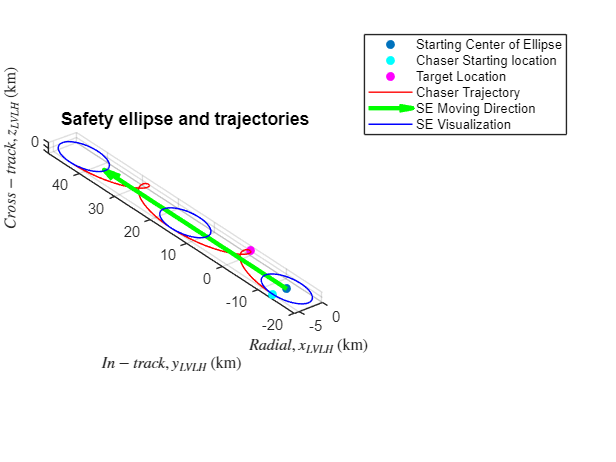

   number_of_periods = 2;

   figure;
   hold on
   grid on


   nt = linspace(0,2*pi*number_of_periods);
   x_t = x_max * cos(nt + alpha) + x_c;
   y_t = -2 * x_max * sin(nt+alpha) + y_c + y_dot_c * nt/n;
   z_t = z_max * cos(nt + beta);
   chaser_trajectory_data = [x_t', y_t', z_t'];
   scatter3(x_c,y_c,0,'filled') % Center of Ellipse
   scatter3(x_0, y_0, z_0,'c','filled') % Chaser Location
   scatter3(0,0,0,'m','filled') % Target Location
   plot3(x_t,y_t,z_t,'red','LineWidth',1)
   q2 = quiver3(x_c,y_c,0,0,y_dot_c*(number_of_periods)*2*pi/n,0,'g','LineWidth',3); % SE Moving Direction

   for period_index = 1:number_of_periods+1
       nt_single = linspace(0,2*pi);
       x_t_single = x_max * cos(nt_single + alpha) + x_c;
       y_t_single = -2 * x_max * sin(nt_single+alpha) + y_c+ y_dot_c*(period_index-1)*2*pi/n;
       z_t_single = z_max * cos(nt_single + beta);
   plot3(x_t_single, y_t_single, z_t_single,'blue','LineWidth',1)
   end


   view(3)
   axis('equal')
   xlabel( '$Radial, x_{LVLH}$ (km)', 'Interpreter', 'latex')
   ylabel('$In-track, y_{LVLH}$ (km)', 'Interpreter', 'latex')
   zlabel('$Cross-track, z_{LVLH}$ (km)', 'Interpreter', 'latex')
   title('Safety ellipse and trajectories','FontSize',12,'FontWeight','bold')
   legend('Starting Center of Ellipse', 'Chaser Starting location', 'Target Location','Chaser Trajectory','SE Moving Direction','SE Visualization')

## III.3 Function for get safety ellipse parmeters

function [x_max, y_max, z_max, x_c, y_c, y_dot_c, alpha, beta] = get_safety_ellipse_params(x_0, y_0, z_0, x_dot_0, y_dot_0, z_dot_0, n)


  x_c = 4*x_0 + 2*y_dot_0/n;
  y_c = -2*x_dot_0/n+y_0;
  y_dot_c = -3*n/2*x_c;
  
  x_max = sqrt((x_dot_0/n)^2+(3*x_0 +2*y_dot_0/n)^2);
  y_max = 2 * x_max;
  z_max = sqrt((z_dot_0/n)^2+z_0^2);

  cos_alpha = -1/x_max * (3*x_0 +2*y_dot_0/n);
  sin_alpha = -1/x_max * (x_dot_0/n);

  if sin_alpha >= 0
    alpha = acos(cos_alpha);
  else
    alpha = 2*pi - acos(cos_alpha);
  end



  cos_beta = z_0/z_max;
  sin_beta = -1/z_max * z_dot_0/n;

  if sin_beta>=0
      beta = acos(cos_beta);
  else
      beta = 2*pi - acos(cos_beta);
  end

  if isnan(beta) == true
   beta = 0;
  end
end

## Appendix 1: 2-body orbit propagator in ECI

function dydt = two_body_dynamics(t,y)

 % Define the standard gravitational parameter for Earth (km^3/s^2)
    mu = 398600.4415;
 
 % Extract position and velocity from the input state vector
    r_vec = y(1:3); % Position vector
    v_vec = y(4:6); % Velocity vector

 % Calculate the norm of the position vector
    r_norm = norm(r_vec);

 % Compute the acceleration based on the gravitational force
   a1 = -mu*r_vec(1)/(r_norm^3);
   a2 = -mu*r_vec(2)/(r_norm^3);
   a3 = -mu*r_vec(3)/(r_norm^3);

 % Combine velocity and acceleration to form the derivative of the state vector
    dydt = [v_vec; a1;a2;a3];
end



function [t,y] = orbit_propagation(r0, v0, tVec)

    odeoptions = odeset('RelTol',1e-10,'AbsTo',1e-20);
    % Calculate the magnitude of the position and velocity vectors
    y0 = [r0;v0];
    
    % Solve the ODE using ode45
    [t, y] = ode45(@two_body_dynamics, tVec, y0, odeoptions);
end

## Appendix 2: ECI to Keplerian Converter (kepler2ijk, ijk2kepler)

function [r,v] = kepler2ijk_hs(a,e,inc,RAAN,AOP,theta)

mu = 398600.4415;

RAAN = RAAN/180*pi;
inc = inc/180*pi;
AOP = AOP/180*pi;
theta = theta/180*pi;


R_3_AOP = [cos(AOP), sin(AOP),0;
           -sin(AOP), cos(AOP),0;
                    0,       0,1];

R_1_inc = [1,       0,         0;
           0, cos(inc),  sin(inc);
           0,-sin(inc),  cos(inc)];

R_3_RAAN = [cos(RAAN), sin(RAAN),0;
           -sin(RAAN), cos(RAAN),0;
                    0,       0,1];


Q_rotation = R_3_AOP * R_1_inc * R_3_RAAN;

p = Q_rotation(1,:);
q = Q_rotation(2,:);
w = Q_rotation(3,:);

p_value = a*(1-e^2);
r = p_value* (cos(theta)*p + sin(theta) *q)/(1+e*cos(theta));
r = r';
v = sqrt(mu/p_value)*(-sin(theta)*p+(e+cos(theta))*q)';
end


function [a, e, inc, RAAN, AOP, theta] = ijk2kepler_hs(r,v)

mu = 398600.4415;

h = cross(r,v);                                   % Angular Velocity Vector
z = [0,0,1]';
n = (cross(z,h))/(norm(cross(z,h)));              % Normal Vector
e_vector = ((cross(v,h))/mu) - r/(norm(r));       % Eccentricity vector


a = (-mu)/((norm(v))^2 - 2*mu/norm(r));           % 1. Semi-major axis
e = norm(e_vector);                               % 2. Eccentricity
inc = acos(dot(z,h)/norm(h)) / pi *180;           % 3. Inclination

RAAN = atan2(n(2),n(1));                          % 4. RAAN
RAAN = RAAN / pi * 180;

AOP = acos((dot(n,e_vector))/norm(e_vector));                   % 5. Argument of periapse
if(e_vector(3)<0)
    AOP = 2*pi - AOP;
end
AOP = AOP/pi*180;

theta = acos((dot(r,e_vector))/(norm(r)*norm(e_vector)));       % 6. True anomaly
if(dot(r,v) < 0)
    theta = 2*pi-theta;
end
theta = theta / pi * 180;
end



## Algorithm 3.4 Coordinate Transform between ECI and LVLH

function [r_lvlh, v_lvlh] = eci2lvlh(r_t_eci, v_t_eci, r_c_eci, v_c_eci, n)

  i_hat = r_t_eci/norm(r_t_eci);
  k_hat = cross(r_t_eci, v_t_eci)/norm(cross(r_t_eci, v_t_eci));
  j_hat = cross(k_hat,i_hat)/norm(cross(k_hat,i_hat));

  Q_lvlh_eci = [i_hat'; j_hat'; k_hat'];

  r_lvlh = Q_lvlh_eci * (r_c_eci - r_t_eci);
  v_lvlh = Q_lvlh_eci * (v_c_eci - v_t_eci - n*cross(k_hat,r_c_eci - r_t_eci));

end




function [r_c_eci, v_c_eci] = lvlh2eci(r_t_eci, v_t_eci, r_lvlh, v_lvlh)

  i_hat = r_t_eci/norm(r_t_eci);
  k_hat = cross(r_t_eci, v_t_eci)/norm(cross(r_t_eci, v_t_eci));
  j_hat = cross(k_hat,i_hat)/norm(cross(k_hat,i_hat));

  Q_eci_lvlh = [i_hat, j_hat, k_hat];

  r_c_eci = Q_eci_lvlh * r_lvlh + r_t_eci;
  v_c_eci = Q_eci_lvlh * v_lvlh + v_t_eci + n* cross(k_hat , r_c_eci - r_t_eci);

end